addpath('Shapes')
load("Data\CFD_confined_TSR_1_1.mat")
X = flow_data(1).X;
Y = flow_data(1).Y;
theta = zeros(length(flow_data),1);
for i = 1:length(flow_data)
    theta(i) = flow_data(i).theta;
end
%thetab = flip(theta);
thetab = 365 - theta;
syms t;
Ry2 = [cosd(t) sind(t); -sind(t) cosd(t)];
thet = [0:pi/32:2*pi,0]';

k = 37

k = 37

alpha = theta(k);
U = flow_data(k).u;
V = flow_data(k).v;
sz = length(X);
Xrot3 = zeros(sz);
Yrot3 = zeros(sz);
for j = 1:sz
    T3 = [X(:,1)';Y(:,j)'];
    XYRy2 = Ry2*T3; 
    res = subs(XYRy2,t,alpha);
    Xrot3(:,j) = res(1,:);
    Yrot3(:,j) = res(2,:);
end
foiltest = plot_foil(theta(k),1);
XYRy2 = Ry2*foiltest';
res = subs(XYRy2,t,alpha);
foiltest(:,:) = res';
%qc = 2.118*[sind(theta(k));cosd(theta(k))];
qc = 2.042*[sind(theta(k));cosd(theta(k))];
qc = Ry2*qc;
qc = subs(qc,t,-alpha);
qc = double(qc);

radius = [1.6 1.7 1.8 1.9 2]./2;
sizes = [1 1.3 1.6 1.9 2.2];
Cin = zeros(length(X),length(X),length(radius))

Cin = Cin(:,:,1) =

     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0 

Ca = zeros(66,2,length(radius))

Ca = Ca(:,:,1) =

     0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0


Ca(:,:,2) =

     0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     

for i = 1:length(radius)
    [Cin(:,:,i),Ca(:,:,i)] = Circle2(qc,radius(i),Xrot3,Yrot3);
end

%[Cin,Ca] = Circle2(qc,1,Xrot3,Yrot3);
qc(1) = qc(1)-1

qc =    -1.0000
    2.0420


Rqcs = [-1.65 -1.85 -2.05 -2.25 -2.45;0 0 0 0 0]

Rqcs =    -1.6500   -1.8500   -2.0500   -2.2500   -2.4500
         0         0         0         0         0


Rqcs = [Rqcs(1,:);Rqcs(2,:)+2.042]

Rqcs =    -1.6500   -1.8500   -2.0500   -2.2500   -2.4500
    2.0420    2.0420    2.0420    2.0420    2.0420


Rin2 = zeros(length(X),length(X),length(Rqcs));
Ra2 = zeros(5,2,length(Rqcs))

Ra2 = Ra2(:,:,1) =

     0     0
     0     0
     0     0
     0     0
     0     0


Ra2(:,:,2) =

     0     0
     0     0
     0     0
     0     0
     0     0


Ra2(:,:,3) =

     0     0
     0     0
     0     0
     0     0
     0     0


Ra2(:,:,4) =

     0     0
     0     0
     0     0
     0     0
     0     0


Ra2(:,:,5) =

     0     0
     0     0
     0     0
     0     0
     0     0


for i = 1:length(Rqcs)
    [Rin2(:,:,i),Ra2(:,:,i)] = Rect2(Rqcs(:,i),0.1,2,Xrot3,Yrot3);
end


[Rin,Ra] = Rect2(qc,0.25,2,Xrot3,Yrot3);
foiltest2 = plot_foil(theta(k),1.5);
XYRy2 = Ry2*foiltest2';
res = subs(XYRy2,t,alpha);
foiltest2(:,:) = res';
Bin = inpolygon(Xrot3,Yrot3,foiltest2(:,1),foiltest2(:,2));

u3 = zeros(sz);
v3 = zeros(sz);
for i = 1:sz
    for j = 1:sz
        XYRy2 = Ry2*[U(i,j);V(i,j)];
        res = subs(XYRy2,t,alpha);
        u3(i,j) = res(1);
        v3(i,j) = res(2);
    end
end

for i = 1:length(radius)
    Umeans.Circle(i) = mean(u3(logical(Cin(:,:,i))));
    Umeans.Rec(i) = mean(u3(logical(Rin2(:,:,i))));
end
for i = 1:length(radius)
    Vmeans.Circle(i) = mean(v3(logical(Cin(:,:,i))));
    Vmeans.Rec(i) = mean(v3(logical(Rin2(:,:,i))));
end

rt = 2.042

rt = 2.0420

Uinf = 0.91

Uinf = 0.9100

lam = 1.1

lam = 1.1000

Omega = lam*Uinf/rt

Omega = 0.4902

bv = Omega*rt.*[-cosd(alpha);-sind(alpha)]

bv =     0.8513
    0.5266


rbv = Rqcs*0

rbv =      0     0     0     0     0
     0     0     0     0     0


for i = 1:length(Rqcs)
    rRef = hypot(Rqcs(1,i),Rqcs(2,i));
    rbv(:,i) = Omega*rRef.*[-cosd(alpha);-sind(alpha)];
end
rbv

rbv =     1.0945    1.1487    1.2063    1.2667    1.3297
    0.6770    0.7105    0.7461    0.7835    0.8224


dTheta = (Umeans.Rec(:,:)+rbv(1,:))./abs(Rqcs(1,:))*Omega

dTheta =     0.1184    0.1252    0.1337    0.1427    0.1482


u4 = zeros(length(u3));
v4 = u4;
for i = 1:length(Xrot3)
    for j = 1:length(Xrot3)
        x = Xrot3(i,j);
        y = Yrot3(i,j);
        rRef = hypot(x,y);
        Omega = lam*Uinf/rt;
        pv = Omega*rRef.*[-cosd(alpha);-sind(alpha)];
        u4(i,j) = u3(i,j)+pv(1);
        v4(i,j) = v3(i,j)+pv(2);
    end
end
Yrot4 = Yrot3-2.042;

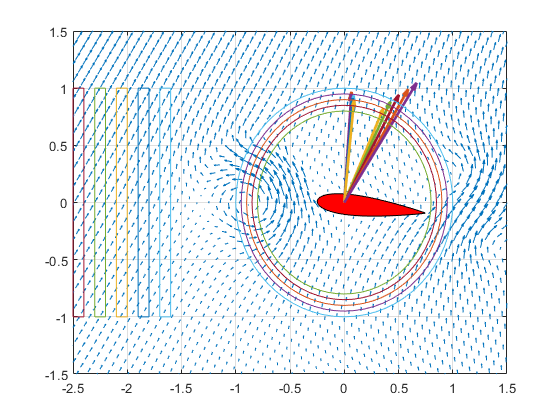

quiver(Xrot3,Yrot4,u4,v4)
xlim([-2.5 1.5])
ylim([-1.5 1.5])
grid on
hold on
fill(foiltest(:,1),foiltest(:,2)-2.042,'r')
for i = 1:length(radius)
quiver(0,0,Umeans.Circle(i)+bv(1),Vmeans.Circle(i)+bv(2),'LineWidth',2)
quiver(0,0,Umeans.Rec(i)+rbv(1,i),Vmeans.Rec(i)+rbv(2,i),'LineWidth',2)
end
for i = 1:length(radius)
    plot(Ca(:,1,i),Ca(:,2,i)-2.042)
    plot(Ra2(:,1,i),Ra2(:,2,i)-2.042)
end
%plot(Ca(:,1),Ca(:,2))
%plot(Ra(:,1),Ra(:,2))
%plot(foiltest2(:,1),foiltest2(:,2),'k')
hold off

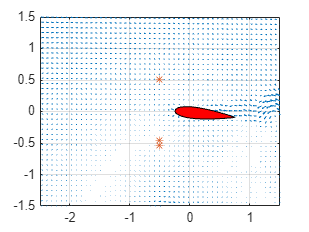

%new 11/19 stuff
quiver(Xrot3,Yrot4,u4,v4)
xlim([-2.5 1.5])
ylim([-1.5 1.5])
grid on
hold on
fill(foiltest(:,1),foiltest(:,2)-2.042,'r')
[Pin,Pa] = Points3(qc,0.5,0.5,Xrot3,Yrot3);
plot(Xrot3(logical(Pin)),Yrot4(logical(Pin)),'*')
hold off

%aoa testing
Urel = [Umeans.Circle(4);Vmeans.Circle(4)]

Urel =    -0.7632
    0.4865


Urel = Urel+bv

Urel =     0.0881
    1.0130


GC = struct;
GC.alphaP = 6;
GC.lambda = lam;

addpath("Subfunctions")
AOA(-bv,Urel,alpha,GC)

ans = 59.2919

alpha

alpha = 211.7373